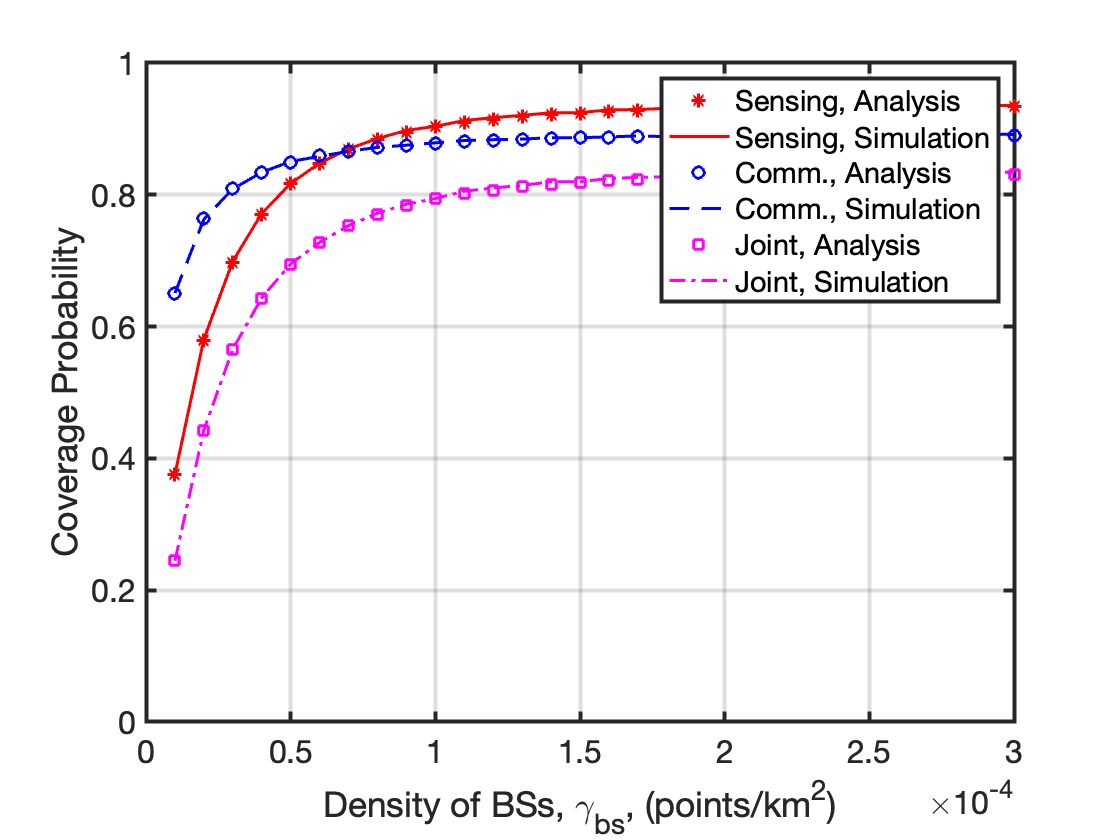

clc;close all;clear all;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
d_prime_s_res=0.2;  %% maximum distance resolution, m

tau_s_0=[0.01]; %%  threshold in sensing

r_c_com_0=[0.5e9];  %% threshold/required data rate in communication

gamma_bs_0= [10:10:300]/1000^2;  %%  density of base station, point/m^2

gamma_sct= 300/1000^2; %% density of SCT, point/m^2

gamma_st= 300/1000^2;   %% density of ST, point/m^2

eta=0.5;  %% first \beta part of the spectrum is allocated to sensing

mu=0.5;  %%  first \mu part of the power is allocated to sensing

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load('data/Ana_P_s_cov_2.mat');
load('data/Sim_P_s_cov_2.mat');

load('data/Ana_P_c_cov_2.mat');
load('data/Sim_P_c_cov_2.mat');


joint_Ana_P_cov_2=Ana_P_s_cov_2.*Ana_P_c_cov_2;
joint_Sim_P_cov_2=Sim_P_s_cov_2.*Sim_P_c_cov_2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure();

plot(gamma_bs_0, Ana_P_s_cov_2,'*r','LineWidth',1.5);hold on;
plot(gamma_bs_0, Sim_P_s_cov_2,'-r','LineWidth',1.5);hold on;


plot(gamma_bs_0, Ana_P_c_cov_2,'ob','LineWidth',1.5);hold on;
plot(gamma_bs_0, Sim_P_c_cov_2,'--b','LineWidth',1.5);hold on;


plot(gamma_bs_0,joint_Ana_P_cov_2,'sm','LineWidth',1.5);hold on
plot(gamma_bs_0,joint_Sim_P_cov_2,'-.m','LineWidth',1.5);hold on


legend('Sensing, Analysis','Sensing, Simulation','Comm., Analysis','Comm., Simulation','Joint, Analysis','Joint, Simulation');
xlabel('Density of BSs, \gamma_{bs}, (points/km^2)');
ylabel('Coverage Probability' );

ylim([0,1]);

set(gca,'LineWidth',2,'FontSize',16);
grid on;